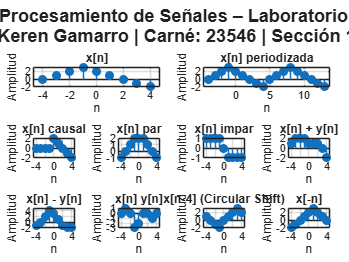

%% Procesamiento de Señales - Laboratorio 2 (Segunda Parte)
% Nombre: Keren Gamarro
% Carné: 23546
% Curso: Procesamiento de Señales
% Sección de Laboratorio: 11

clear              % Elimina todas las variables del Workspace
clc                % Limpia la ventana de comandos
close all           % Cierra todas las figuras abiertas

%% Definición de las señales discretas
n = -4:4;           % Vector de índice discreto n

x = [0 1 2 3 2 1 0 -1 -2];   % Señal discreta x[n]
y = [1 1 0 -1 -1 0 1 1 0];   % Señal discreta y[n]

%% Creación de la figura y del layout general
figure              % Crea una nueva figura
tiledlayout(3,4,'TileSpacing','compact','Padding','compact')
% Se crea una distribución de 3 filas y 4 columnas para las subfiguras, los
%siguientes comandos indicando el tipo de presentación que se quiere, el
%espaciado y padding que es el espacio libre entre las graficas

%% 1) Gráfica de la señal x[n]
nexttile([1 2])     % La subfigura ocupa 1 fila y 2 columnas, de esta manera se ve mas grande que las de abajo de ella
stem(n,x,'filled')  % Representación discreta de x[n] con puntos llenos
title('x[n]')       % Título de la subfigura
xlabel('n')         % Etiqueta del eje horizontal
ylabel('Amplitud')  % Etiqueta del eje vertical
grid on             % Activa la cuadrícula

%% 2) Gráfica de x[n] periodizada (un período adicional)
x_per = [x x];                  % Se repite la señal x[n]
n_per = [n n+length(n)];        % Se ajusta el índice para el nuevo período, sumandole su largo a n

nexttile([1 2])     % Ocupa 1 fila y 2 columnas
stem(n_per,x_per,'filled')
title('x[n] periodizada')
xlabel('n')
ylabel('Amplitud')
grid on

%% 3) Conversión de x[n] en una señal causal
x_causal = x;        % Copia de la señal original
x_causal(n<0) = 0;   % Se hace cero para n < 0 (condición de causalidad vista en teoria)

nexttile
stem(n,x_causal,'filled')
title('x[n] causal')
xlabel('n')
ylabel('Amplitud')
grid on

%% 4) Conversión de x[n] en una señal par
x_par = (x + fliplr(x))/2;   % Definición matemática de señal par

nexttile
stem(n,x_par,'filled')
title('x[n] par')
xlabel('n')
ylabel('Amplitud')
grid on

%% 5) Conversión de x[n] en una señal impar
x_impar = (x - fliplr(x))/2; % Definición matemática de señal impar

nexttile
stem(n,x_impar,'filled')
title('x[n] impar')
xlabel('n')
ylabel('Amplitud')
grid on

%% 6) Suma de señales: x[n] + y[n]
nexttile
stem(n,x+y,'filled')     % Suma punto a punto de las señales
title('x[n] + y[n]')
xlabel('n')
ylabel('Amplitud')
grid on

%% 7) Resta de señales: x[n] − y[n]
nexttile
stem(n,x-y,'filled')     % Resta punto a punto de las señales
title('x[n] - y[n]')
xlabel('n')
ylabel('Amplitud')
grid on

%% 8) Multiplicación de señales: x[n] y[n]
nexttile
stem(n,x.*y,'filled')    % Multiplicación elemento a elemento, se usa el .
title('x[n] y[n]')
xlabel('n')
ylabel('Amplitud')
grid on

%% 9) Corrimiento circular de la señal x[n − 4]
x_shift = circshift(x,4);  % Desplazamiento circular de 4 muestras

nexttile
stem(n,x_shift,'filled')
title('x[n-4] (Circular Shift)')
xlabel('n')
ylabel('Amplitud')
grid on

%% 10) Inversión temporal: x[-n]
x_inv = fliplr(x);        % Inversión del orden de la señal

nexttile
stem(n,x_inv,'filled')
title('x[-n]')
xlabel('n')
ylabel('Amplitud')
grid on

%% Título global de la figura
sgtitle({'Procesamiento de Señales – Laboratorio 2'; ...
         'Keren Gamarro | Carné: 23546 | Sección 11'}, ...
         'FontWeight','bold')

% Título general que describe la figura completa
